## Benjamin Rosenberg    EECE 5644    Take Home Exam 3

# Question 1

For this question, a multilayer perceptron (MLP) was used to estimate class-label posteriors of various datasets. The MLP was trained to minimize cross-entropy loss, which achieves maximum-likelihood estimation of the MLP parameters for a given dataset.

This can be seen by derivation from maximum likelihood parameter estimation, given dataset $D=\{(x_1,l_1),...,(x_N,l_N)\}$ and parameter vector $\theta$:


$$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmax}\ p(D|\theta)$$


which can be shown to equal


$$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmax}\Big\{\sum_{n=1}^Nln(p(l_n|x_n,\theta)\Big\}$$


If we let the output to an MLP for a given sample $l_n$ be  $h_{l_n}(x_n,\theta) \approx p(l_n|x_n,\theta)$, then


$$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmax}\Big\{\sum_{n=1}^Nln(h_{l_n}(x_n,\theta)\Big\}$$


By introducing a cross-entropy vector $y_{(l)_n}$that contains zeros except for a 1 at the row $l$ corresponding to the current sample label, then rewriting to a minimization problem, we get:


$$\hat{\theta}_{ML}=
\underset{\mathbf{\theta}}{argmin}\Big\{-\frac{1}{N}\sum_{n=1}^N\Big[\sum_{l=1}^{N}y_{(l)_n} ln(h_{l_n}(x_n,\theta)\Big]\Big\}$$


which is known as the minimum cross-entropy loss function. As stated above, this is the loss function used to calculate MLP performance while training. These equations were provided in the course document "Approximating Class Posteriors With a Model Function..." by Prof. Deniz Erdogmuz.

### MLP Structure

The MLP consisted of a hidden layer, an activation function (sigmoid or tanH) between, then an output layer with a softmax function to normalize the MLP outputs as probabilities. The tanH activation function was selected for its differentiability across all input values, and its good performance with the "Xavier" initialization process, described in the MLP initialization section below. The weights and biases of the MLP are vectorized for training as $\theta = \{b,A,d,C\}$, where $b$ is the input layer bias, $A$ is a matrix of the input layer weights, $d$ is the hidden layer bias, and $C$is a matrix of the hidden layer weights. The MATLAB function 'patternnet' was used to implement the MLP as described. A MATLAB output of the MLP with 6 perceptrons using the tanH activation function is shown below:

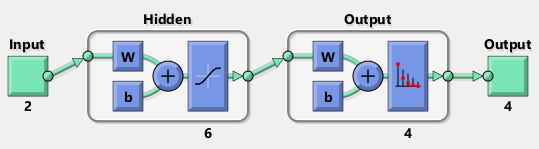

### MLP Initialization

Various MLP initializations were attempted, including initializing all biases and weights to zeros, initializing all biases and weights to uniform random values, and the "Xavier" initialization approach as explained in "Understanding the difficulty of training deep feedforward neural networks" by Glorot and Bengio. The Xavier initialization yielded the fastest training times and lowest P(error) for validation and testing datasets. In the Xavier initialization, the MLP layer weights $A$ and $C$ are initialized with random values from the distribution $U\Big[-\frac{\sqrt{6}}{\sqrt{n_j + n_{j+1}}},\frac{\sqrt{6}}{\sqrt{n_j + n_{j+1}}}\Big]$, where $n_j$ is the dimensionality of the input to a layer, and $n_{j+1}$ is the dimensionality of the output to a layer. The bias values are set to zeros. The MATLAB code for this initialization of the MLP is in init_mlp.m, and xavier_init.m includes Xavier initialization details.

### Model Order Selection

10-fold cross-validation was used to determine model order selection. In this case, model order selection was the optimal number of perceptrons at the hidden layer from {1,...,8} and the activation function for the hidden layer, either sigmoid or tanH. All samples were generated using the provided generateMultiringDataset.m, with $C=4$ classes, training sets $D_{train}$ of 100, 500 and 1000 samples, and a testing set $D_{test}$ of 10,000 samples. For each $D_{train}$ set, 10-fold cross-validation was performed, using all combinations of input perceptrons {1,...,8} and the two activation functions. The MLP was trained using backpropogation on data from all of the designated training folds, and tested using the validation fold. A new fold was then selected for validation, with the remainder of folds used to train the MLP, and this process was repeated until all folds were used for validation. An estimated classification error probability $P(error) = \frac{\text{incorrect}}{\text{total}}$ for each validation fold was calculated for all of these combinations. At the end of a 10-fold cross-validation cycle for a given perceptron-activation function combination, a mean P(error) was calculated from all validation folds, and stored in a matrix for later selection. After all model order combinations were tested for a training set, the number of perceptrons and activation function corresponding to the minimum entry in the mean P(error) matrix was selected as the model order. The file model_order_selection.m includes code implementing the model order selection process.

### Results

The plots below include data samples produced by generateMultiringDataset.m, and bar graphs of the mean P(error) results of 10-fold cross-validation for the training datasets. Outputs of the selected model order are also printed below each bar graph. Across several iterations of this 10-fold-cross-validation cycle for each training set, the optimal model parameters were observed to be between 5-7 perceptrons, while the tanH activation function yielded better performance regardless of the training dataset size or iteration of cross-validation. The exception to these observations was the the 100 sample training set, where there did not appear to be enough samples for effective cross-validation, and the number of perceptrons and activation function for model order selection fluctuatued.

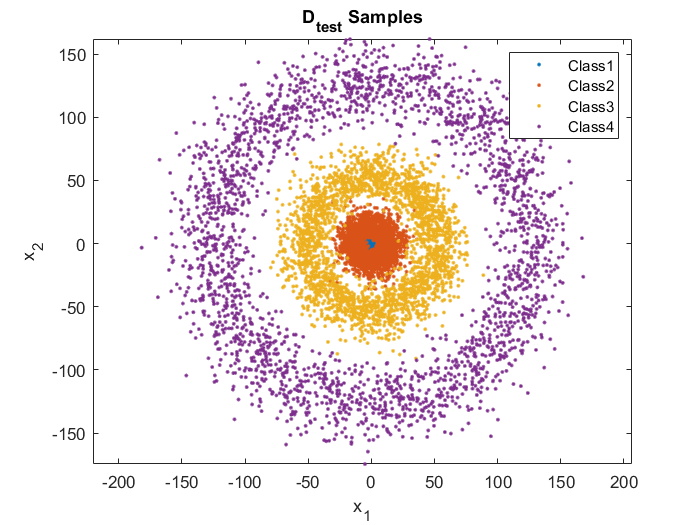

% Number of classes
C = 4;
% Create test dataset
[test_set,test_labels] = generateMultiringDataset(C,10000);
plot_samples(test_set,test_labels,C,'D_{test} Samples');

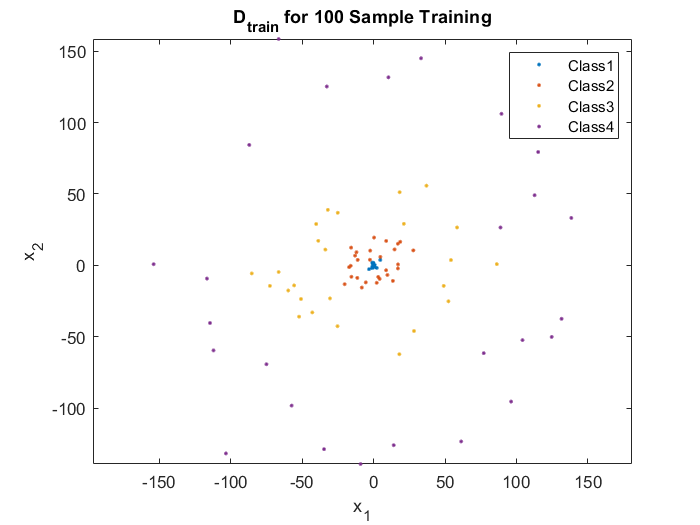

% Generate 100 sample training dataset
[training_set_100,training_labels_100] = generateMultiringDataset(C,100);
plot_samples(training_set_100,training_labels_100,C,'D_{train} for 100 Sample Training');

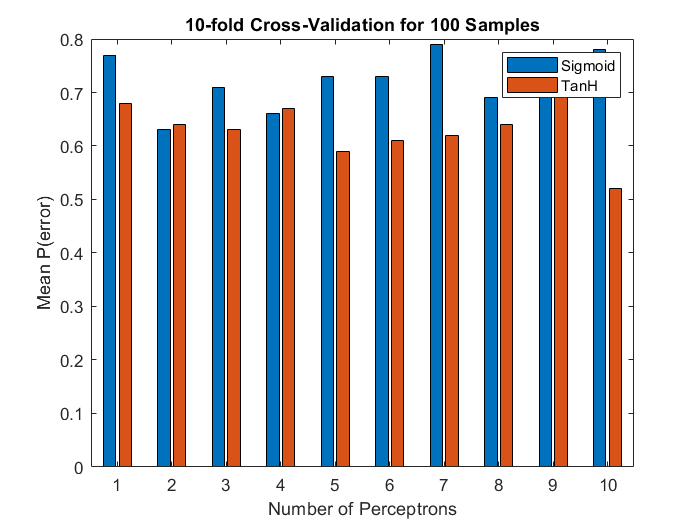

Model Order Selection for 100 Samples
Number of Perceptrons: 10
Activation Function: TanH

% Model order selection using training dataset
[num_perceptrons,fn] = model_order_selection(training_set_100,training_labels_100,C);

% Initialize MLP as determined by model order selection
y_train = labels_to_y(training_labels_100,C);
mlp = init_mlp(num_perceptrons,fn,training_set_100,y_train);
% Train MLP using full training dataset
mlp = train(mlp,training_set_100,y_train);

% Validate MLP performance on test dataset
H = mlp(test_set);

% Use MAP classification on test data
[~,mlp_labels] = max(H,[],1);
P_error_100 = sum(test_labels ~= mlp_labels)/numel(test_labels);
fprintf('P(error) for 100 samples: %f',P_error_100);

P(error) for 100 samples: 0.640800

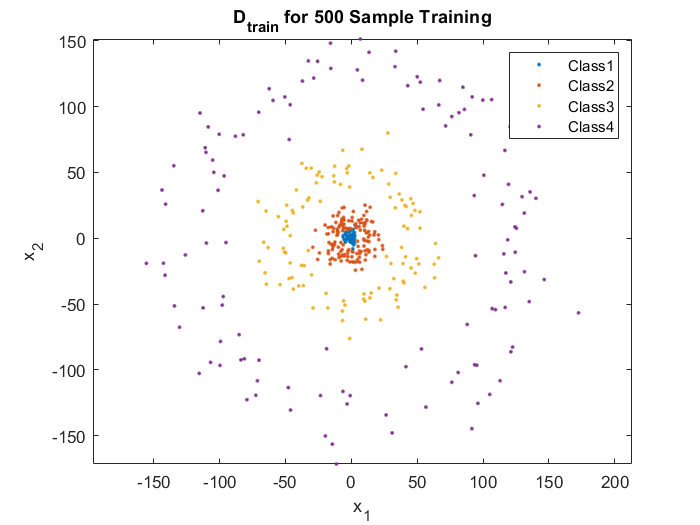

% Generate 500 sample training dataset
[training_set_500,training_labels_500] = generateMultiringDataset(C,500);
plot_samples(training_set_500,training_labels_500,C,'D_{train} for 500 Sample Training');

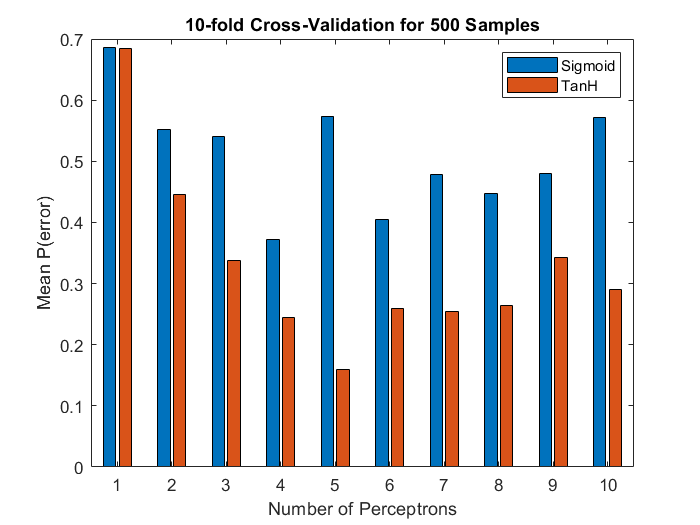

Model Order Selection for 500 Samples
Number of Perceptrons: 5
Activation Function: TanH

% Model order selection using training dataset
[num_perceptrons,fn] = model_order_selection(training_set_500,training_labels_500,C);

% Initialize MLP as determined by model order selection
y_train = labels_to_y(training_labels_500,C);
mlp = init_mlp(num_perceptrons,fn,training_set_500,y_train);
% Train MLP using full training dataset
mlp = train(mlp,training_set_500,y_train);

% Validate MLP performance on test dataset
H = mlp(test_set);

% Use MAP classification on test data
[~,mlp_labels] = max(H,[],1);
P_error_500 = sum(test_labels ~= mlp_labels)/numel(test_labels);
fprintf('P(error) for 500 samples: %f',P_error_500);

P(error) for 500 samples: 0.291200

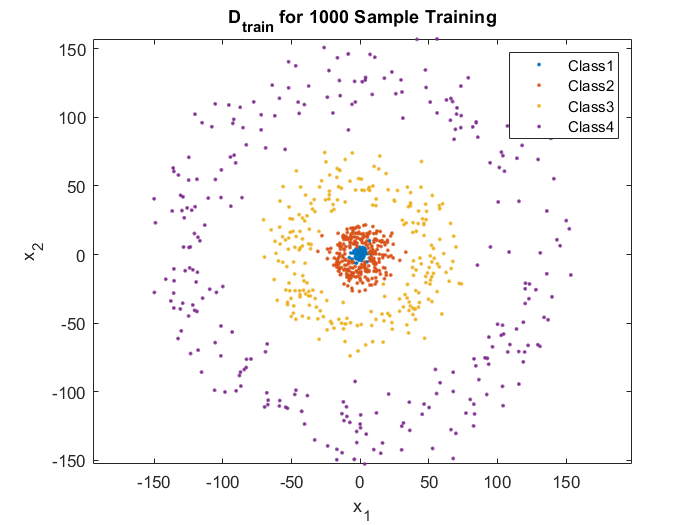

% Generate 1000 sample training dataset
[training_set_1000,training_labels_1000] = generateMultiringDataset(C,1000);
plot_samples(training_set_1000,training_labels_1000,C,'D_{train} for 1000 Sample Training');

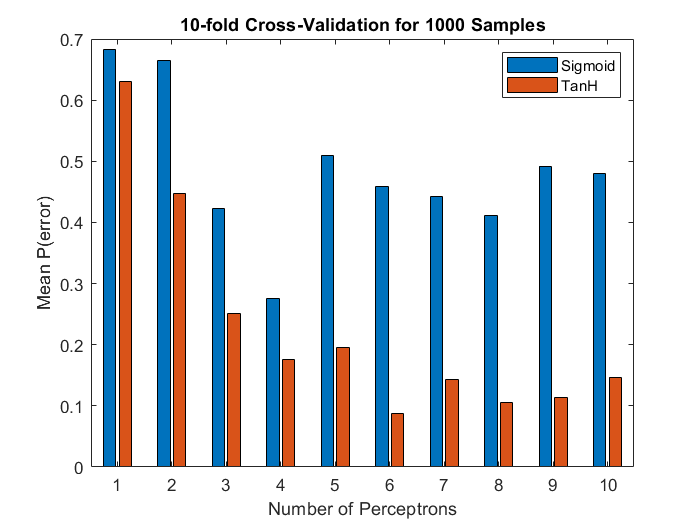

Model Order Selection for 1000 Samples
Number of Perceptrons: 6
Activation Function: TanH

% Model order selection using training dataset
[num_perceptrons,fn] = model_order_selection(training_set_1000,training_labels_1000,C);

% Initialize MLP as determined by model order selection
y_train = labels_to_y(training_labels_1000,C);
mlp = init_mlp(num_perceptrons,fn,training_set_1000,y_train);
% Train MLP using full training dataset
mlp = train(mlp,training_set_1000,y_train);

% Validate MLP performance on test dataset
H = mlp(test_set);

% Use MAP classification on test data
[~,mlp_labels] = max(H,[],1);
P_error_1000 = sum(test_labels ~= mlp_labels)/numel(test_labels);
fprintf('P(error) for 1000 samples: %f',P_error_1000);

P(error) for 1000 samples: 0.069000

### Final Model Testing

This final model order, as selected using 10-fold cross-validation explained above, was used to create and train an MLP using the entire $D_{train}$ set, and test the MLP by classifying samples in $D_{test}$ with the MAP classification rule. The output of the MLP for a given sample approximates a vector of class posteriors, i.e. $[P(L=1|\mathbf{x_n}) \ ... \ P(L=C|\mathbf{x_n})]^T$ for C classes, so we can use the rule $L_{MAP}=
\underset{\mathbf{n}}{argmax}\ p(L=n|\theta)$, where $L_{MAP}$ is the label selected from MAP classification using the final MLP. The bar graph below includes P(error) estimates for the final MLPs classifying samples in the $D_{test}$ dataset.These values are also included as output in the model order selection section above. Test performance improves drastically with increasing training dataset sizes. Larger training datasets allow for more accurate model-order selection, because each 10-fold training set is larger, and can better demonstrate the effect of changing activation function and perceptron count on MLP performance. In addition, larger training datasets allow the final MLP weights to converge closer to optimal values for classification of the 10,000 sample testing set.

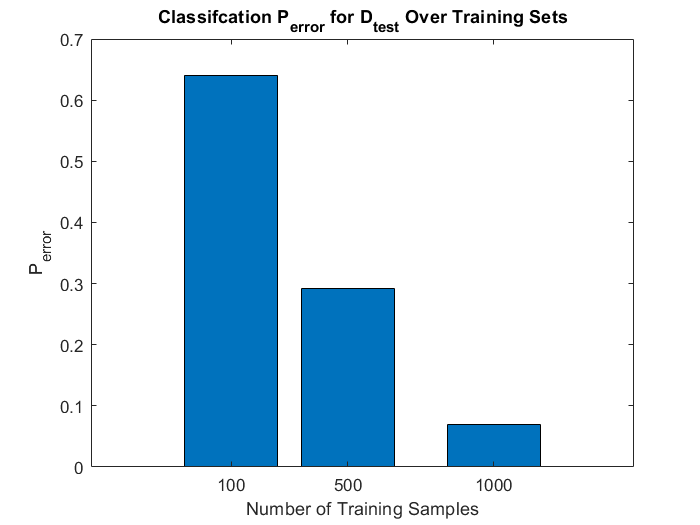

bar([100 500 1000],[P_error_100 P_error_500 P_error_1000]);
xlabel('Number of Training Samples'); ylabel('P_{error}');
title('Classifcation P_{error} for D_{test} Over Training Sets');

# Question 2

For this question, GMMs were used to predict class labels for datasets from generateMultiringDataset.m. We first estimated class prior probabilities for classes $C = \{1,...,4\}$ from a given training dataset as (number of samples for class label)/(total number of samples), implemented in estimate_priors.m. Then, GMMs were trained using the expectation maximization algorithm and 10-fold cross-validated datasets to determine optimal model order, or number of Gaussian mixture components. 

### Model Order Selection

The GMM model order selection process was as follows for each class label:

1. Filter a given training dataset by class label, and for a given class label, partition the training dataset into 10 folds.

2. Select one of the folds as a validation set, and the rest of the samples as training data.

3. Using these validation and training sets, assess the performance of each model order in the range of M = {1,...,6}. Performance is measured using log-likelihood of the model with the validation dataset.

4. Repeat steps 2 and 3, until all folds have been used for validation once.

4. Find the mean performance values for each model order across all folds, and select the maximum mean value as the optimal model order.

From the optimal model order, a new GMM was trained for each class label. 

### Results

The bar graph below shows model order selection for each class over the 100, 500, and 1000 sample training datasets. As number of samples in the training datasets increased, the model order selection tended to increase. However, for class label 1, we see the model order selection increase less than the other class labels with each dataset. This is due to the tightly clustered shape of the class 1 data distritibtuion (see test and training sample plots in question 1).

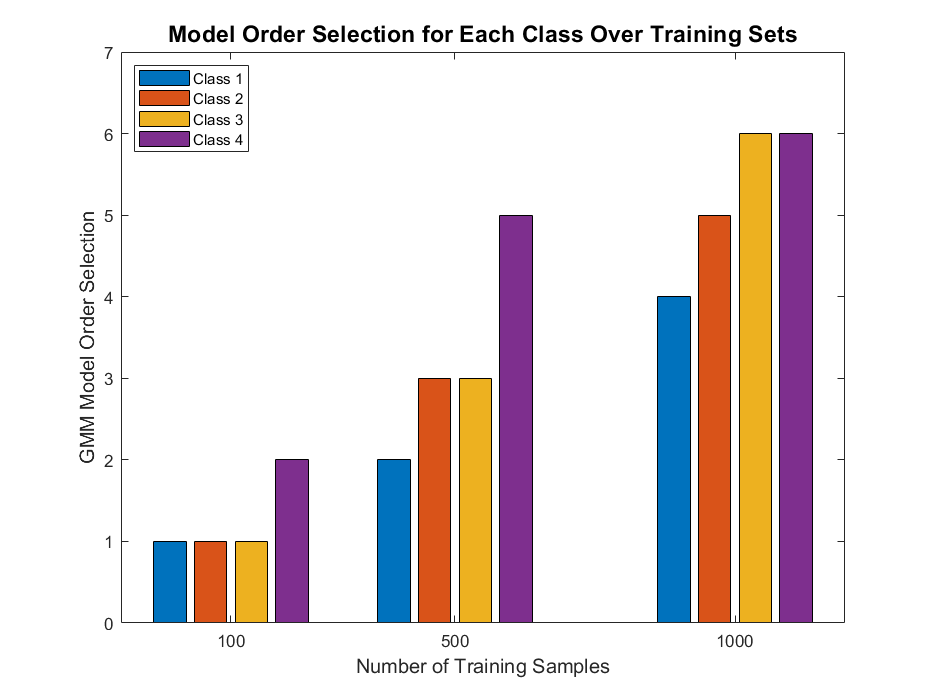

% Store model-order selections for all classes and all datasets
model_orders = zeros(C,3);

priors = estimate_priors(training_labels_100,C);
delta = 1e-3;
% Initialize GMM parameter arrays
alpha = {}; mu = {}; Sigma = {};
for jj = 1:C
    class_samples = training_set_100(:,training_labels_100 == jj);
    % Find the best model order for the data
    M = gmm_model_order(class_samples,delta);
    model_orders(jj,1) = M;
    % Fit the final GMM based off model order selection
    [alpha{jj},mu{jj},Sigma{jj}] = gmm_expectation_maximization(M,class_samples,delta);
end
gmm_labels = gmm_map_classifier(test_set,C,alpha,mu,Sigma,priors);

priors = estimate_priors(training_labels_500,C);
delta = 1e-3;
% Initialize GMM parameter arrays
alpha = {}; mu = {}; Sigma = {};
for jj = 1:C
    class_samples = training_set_500(:,training_labels_500 == jj);
    % Find the best model order for the data
    M = gmm_model_order(class_samples,delta);
    model_orders(jj,2) = M;
    % Fit the final GMM based off model order selection
    [alpha{jj},mu{jj},Sigma{jj}] = gmm_expectation_maximization(M,class_samples,delta);
end
gmm_labels = gmm_map_classifier(test_set,C,alpha,mu,Sigma,priors);
P_error_GMM_500 = sum(test_labels ~= gmm_labels)/numel(test_labels);

priors = estimate_priors(training_labels_1000,C);
delta = 1e-3;
% Initialize GMM parameter arrays
alpha = {}; mu = {}; Sigma = {};
for jj = 1:C
    class_samples = training_set_1000(:,training_labels_1000 == jj);
    % Find the best model order for the data
    M = gmm_model_order(class_samples,delta);
    model_orders(jj,3) = M;
    % Fit the final GMM based off model order selection
    [alpha{jj},mu{jj},Sigma{jj}] = gmm_expectation_maximization(M,class_samples,delta);
end
gmm_labels = gmm_map_classifier(test_set,C,alpha,mu,Sigma,priors);
P_error_GMM_1000 = sum(test_labels ~= gmm_labels)/numel(test_labels);

h = bar([100 500 1000],model_orders'); ylim([0 7]);
set(h,{'DisplayName'},{'Class 1','Class 2','Class 3','Class 4'}'); 
legend('show','location','northwest');
xlabel('Number of Training Samples'); ylabel('GMM Model Order Selection');
title('Model Order Selection for Each Class Over Training Sets');

### MAP Classification Using GMMs

With the final trained GMMs from model order selection as described above, a MAP classifier was created using the formula $p(L=n|\mathbf{x}) = p(L=n)p(\mathbf{x}|L=n)$, where $p(L=n|\mathbf{x})$ is the class posterior for class n, $p(L=n)$ is the estimated class prior for class n from the training dataset, and $p(\mathbf{x}|L=n)$ is the class-conditional pdf for class n as determined from the GMM expectation maximization algorithm. The MAP classification rule and  $L_{MAP}=
\underset{\mathbf{n}}{argmax}\ p(L=n|\mathbf{x})$ selects the class with the highest class posterior value. 

The class-conditional pdf was composed of the trained GMM from the model order selection process for each class, $p(\mathbf{x}|L=n) = \alpha_1P(\mathbf{x}|\alpha_1, L=n)P(L=n)+...+\alpha_mP(\mathbf{x}|\alpha_m, L=n)P(L=n)$, where the weights $\alpha_1,...,\alpha_m$ are the weights of each mixture component in the m-th order GMM, and $P(\mathbf{x}|\alpha_m, L=n)$ is the m-th Gaussian component for the mixture of label n samples. This MAP classification procedure using GMMs is implemented in gmm_map_classifier.m.

### Results

Below are outputs for MAP classification P(error) of the final trained GMMs for each dataset evaluated against the test dataset. Also included is a bar graph of the same data. Clearly, performance of the final GMMs increased with a higher number of training samples. Overall, the results for GMM MAP classification are better than those of the MLP MAP classification in question 1. Datasets generated using generateMultiringDataset.m are circular sets for each class label (see plots in question 1), therefore they are structured to fit GMMs well. A GMM with overlapping zero-mean components and covariance matrices of increasing eigenvaluevalue closely approximates the data distribution. 

fprintf('P(error) for 100 sample training set: %f',P_error_GMM_100);

P(error) for 100 sample training set: 0.087000

fprintf('P(error) for 500 sample training set: %f',P_error_GMM_500);

P(error) for 500 sample training set: 0.038400

fprintf('P(error) for 1000 sample training set: %f',P_error_GMM_1000);

P(error) for 1000 sample training set: 0.027500

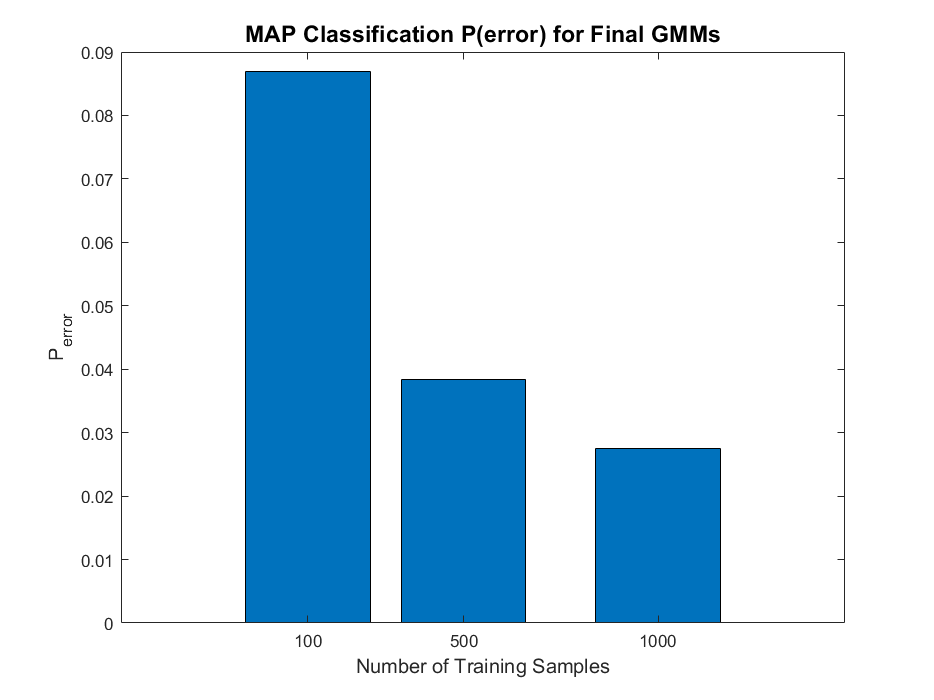

bar([100 500 1000],[P_error_GMM_100 P_error_GMM_500 P_error_GMM_1000]);
xlabel('Number of Training Samples'); ylabel('P_{error}');
title('MAP Classification P(error) for Final GMMs');